# 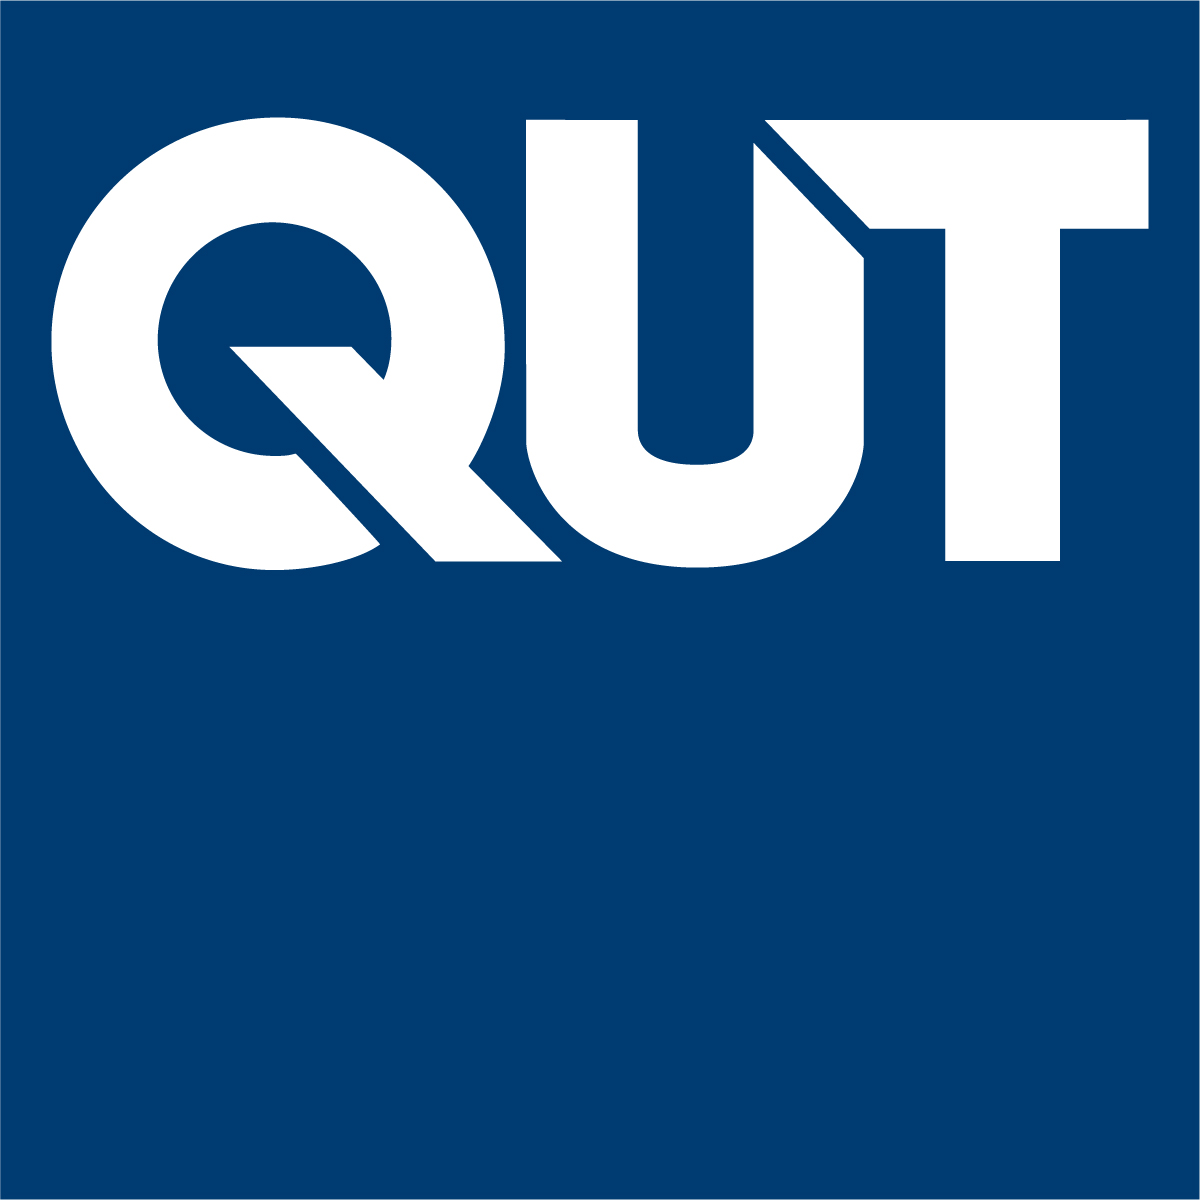

# MXB201 Chapter 3: Gram-Schmidt and QR decomposition

Professor Tim Moroney,  2022

V1.0

## 3.1 Introduction

In this chapter we will consider how to represent vectors using different bases.  We will learn that some bases are much more convenient to use than others.  In particular, bases that are *orthonormal* will prove to be the most convenient, and we'll learn how to build orthonormal bases.

Before we dive in, it's worth reflecting briefly just what actually *is* a vector.  In linear algebra, when we say "vector", we mean an element of an abstract vector space.  This vector space might be $\mathbb{R}^n$, in which case the vector could be identified with a point in this Euclidean space.  But be careful to distinguish between a vector, and its *representation* in terms of some basis.  The vector itself "just is", while the representation we use depends on our choice of basis.  For example, we *could *represent a vector in $\mathbb{R}^3$ in terms of the *standard basis* $\{i, j, k\}$, in which case its representation might be $v = 2i + 3j-k$ (or whatever).  We could even simplify this notation by dispensing with the explicit mention of $i$, $j$ and $k$, and just using the column of numbers $\left\lbrack \begin{array}{c}
2\\
3\\
-1
\end{array}\right\rbrack$to represent the vector, with the understanding that this column of numbers is to be interpreted as the coefficients of the basis vectors.

Unfortunately in mathematics the term "vector" is seriously overloaded, so we can *also *call the column of numbers itself a "vector".  It would often be referred to as the *coordinate vector* of $v$, relative to the standard basis.   But note that this is a *distinct* meaning of "vector".  While hopefully the context makes it clear what is meant by the term "vector", there is a chance for confusion if you're not careful.  For example, it's perfectly possible to represent the *same vector *$v$ (which is a vector in the abstract vector space sense) by *different coordinate vectors*.  Just change your basis from $\{i, j, k\}$ to something else and the vector $v$ will now be represented by a different column of numbers to the one above: $v$ hasn't changed, but its *representation *has.

This chapter is all about finding convenient representations of vectors.  That is, finding convenient bases.

In this chapter, we will use *floating point arithmetic* rather than exact arithmetic.  There will be a lot of square roots floating around, so the exact arithmetic expressions quickly get unwieldy.

[Video](https://web.microsoftstream.com/video/e1ed4097-17b9-48ac-a6ef-4379bf7ca8e9)

Let's revisit this simple example in MATLAB.  In $\mathbb{R}^2$, the standard basis consists of the vectors $i$ and $j$, or, as we'll call them, $e_1$ and $e_2$.  We prefer the names $e_1$ and $e_2$, as it means we can easily generalise to any dimension, whereas using $i,j,k,$ etc. quickly exhausts all available letters!

e1 = [1; 0], e2 = [0; 1]  % the "i" and "j" vectors in R^2

e1 =      1
     0


e2 =      0
     1


A vector like

b = [3; 2] 

b =      3
     2


is understood to mean $b = 3e_1 + 2e_2$.  We can visualise how the vector $b$, represented graphically by an arrow from the origin to the point $(3,2)$, breaks down into the sum of 3 times $e_1$ plus 2 times $e_2$.

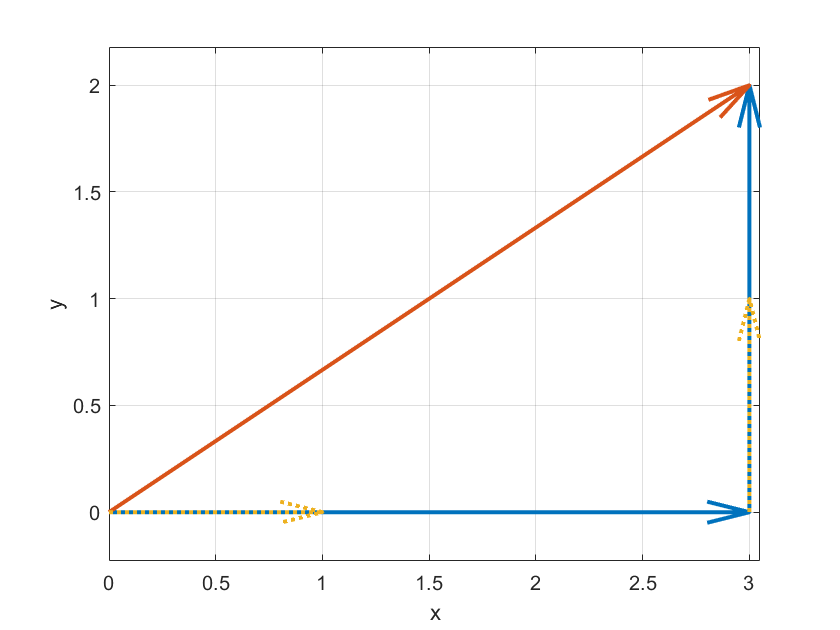

figure
plot_lincomb(b, eye(2))

(The function `plot_lincomb` is included with this chapter's lecture notes to download.  It's not important to study to code; its only role is to make these pretty pictures.)

In this figure, the raw basis vectors $e_1, e_2$ are shown in dotted yellow, and these are scaled by the provided coefficients to give the vectors $3e_1, 2e_2$ in blue.  The blue vectors are added, tip-to-tail, to produce the final vector $b$ in red.

We call the column vector $\left[\matrix{3 \cr 2}\right]$ the *coordinate vector* of $b$ *relative to the standard basis* $S = \{{e_1, e_2\}$.  We might even write this as $(b)_S = \left[\matrix{3 \cr 2}\right]$, where this bracket notation means the coordinate vector of the thing in the brackets, here it's $b$, relative to the basis in the subscript, here it's $S$.  But for the standard basis $S$, there is usually no confusion if we simply write $b = \left[\matrix{3 \cr 2}\right]$, meaning we identify $b$ with its column vector representation in terms of the standard basis.

## 3.2 Changing basis

It's certainly possible to represent the same vector $b$ in terms of a different basis.  Consider the basis $W = \{w_1, w_2\}$ given by

w1 = [2; -1]; w2 = [-1; 3]

w2 =     -1
     3


and we want to know what is the *coordinator vector* of $b$ relative to this new basis $W$: what is $(b)_W$?

[Video](https://web.microsoftstream.com/video/af532f94-8b74-49e6-9358-3b9876717e1a)

#### Exercise

On a piece of paper, go through this same example yourself by hand.  Don't refer to back to the video unless you really get stuck.▫

As we saw in the video, really, we are asking the question: what linear combination of these basis vectors $w_1,w_2$ equals $b$?  Letting the unknown coefficients be $c_1, c_2$, we want to solve $c_1 w_1 + c_2 w_2 = b$.  As we've seen many times up to now, this is just the linear system $Wc = b$ where the columns of $W$ are $w_1, w_2$.  Hence, the linear combination we seek is found by augmenting the basis vectors as columns to form $W$, and then solving $Wc = b$.

W = [w1 w2]

W =      2    -1
    -1     3


c = W \ b

c =     2.2000
    1.4000


Let's confirm graphically that the linear combination $c_1 w_1 + c_2 w_2$ does indeed equal $b$.

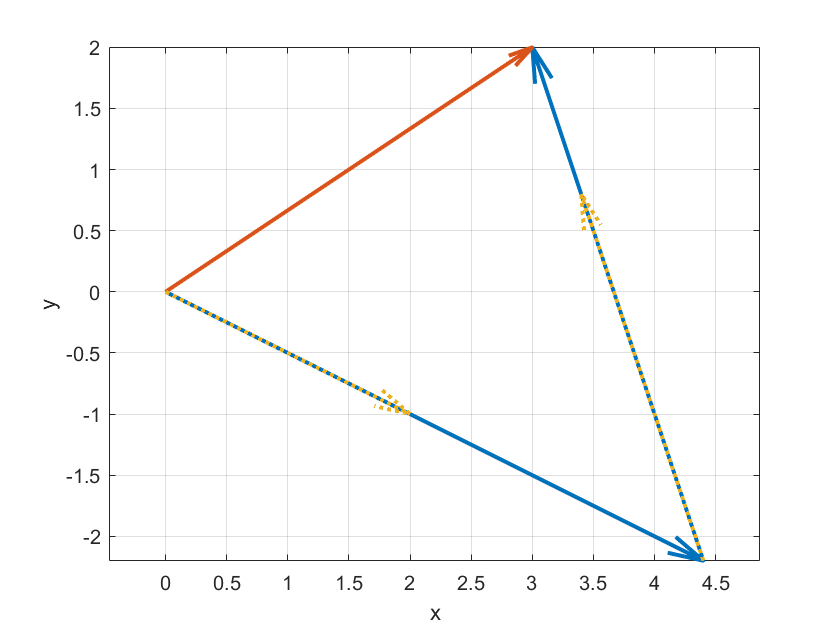

figure
plot_lincomb(c, W)

Here we see the new basis vectors $w_1,w_2$ in dotted yellow, which are again scaled by the provided coefficients to give the vectors $2.2w_1, 1.4w_2$ in blue.  Adding the blue vectors tip-to-tail gives same the red vector as before.  So we now have two different representations of the same vector $b$.  In terms of the standard basis $S = \{e_1, e_2\}$, its representation is the coordinate vector $(b)_S = \left[\matrix{3 \cr 2}\right]$.  In terms of the basis $W = \{w_1, \ w_2\}$ its representation is the coordinator vector $(b)_W = \left[\matrix{2.2\cr 1.4}\right]$.  Either way, we are referring to the exact same vector in two-dimensional space: it's the red arrow in either figure.

So in general, to convert from a representation of a vector in one basis to its representation in another basis requires solving a linear system of equations.

Now actually, that's a bit of pain.  Having to solve a linear system of equations just to convert between bases makes the whole process less convenient than it might otherwise be.

But there is a way to make the whole situation much more convenient.  Let's look again at our two representations of $b$, but now overlayed on the same figure.

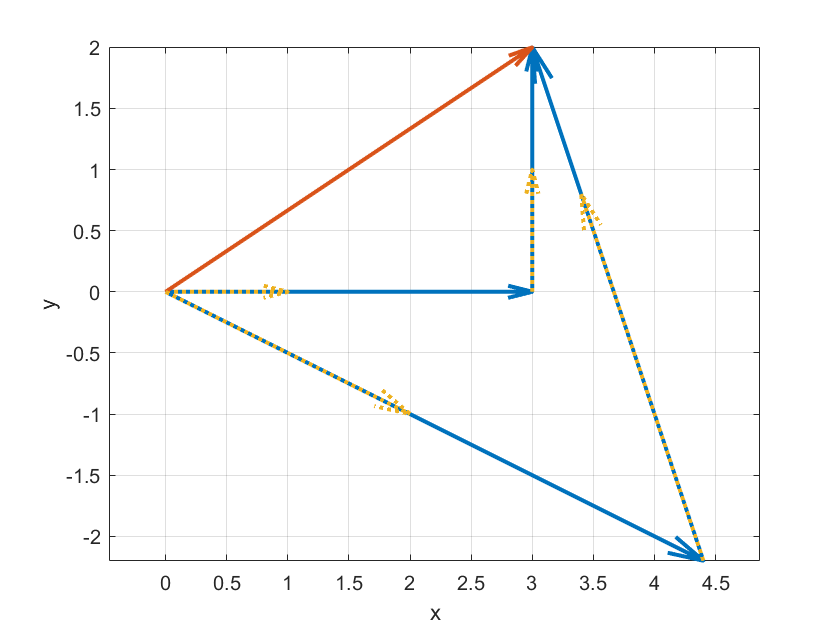

figure
plot_lincomb(b, eye(2));
hold on
plot_lincomb(c, W)

The reason the standard basis $S = \{e_1, e_2\}$ is so easy to work with, is that it comprises *unit vectors* which are *mutually orthogonal*.  Look at the figure: the yellow vectors $e_1$ and $e_2$ have lengths of one and are at right angles to each other.  Such a basis is called an ***orthonormal basis****: "*ortho" short for "orthogonal", and "normal" meaning "of unit length".

Contrast this to our second basis $W = \{w_1, w_2\}$: the yellow basis vectors have lengths different from one (and different from each other) and they are certainly not orthogonal.

Let's explore further now, what simplifications arise from working with an orthonormal basis.

[Video](https://web.microsoftstream.com/video/fb00c426-d8cf-4920-8ef7-c8b4fa5883c0)

### 3.2.1 Converting to an orthonormal basis

We saw in the last video how much simpler things become if we have an orthonormal basis, which we might call $\{q_1, q_2\}$.  So consider the following question: is there a way to take the basis $\{w_1, w_2\}$ and *convert *it to an orthonormal basis?

[Video](https://web.microsoftstream.com/video/c6fb233d-e449-4f65-b8fb-0e7dcc8dc037)

#### Exercise

On a piece of paper, go through this same process of orthonormalising the basis yourself by hand.  Don't refer to back to the video unless you really get stuck.▫

Let's follow the process in MATLAB.  First, divide the first basis vector $w_1$ by its length, in order to normalise it (i.e. make its length one).  Call the result $q_1$.

q1 = w1 / norm(w1)

q1 =     0.8944
   -0.4472


Now, the second basis vector $w_2$ isn't orthogonal to $q_1$.  It just isn't.  But we won't give up on the idea.  Instead of using $w_2$ in our orthonormal basis, we will take the "nearest thing to $w_2$" that *is* orthogonal to $q_1$.  That is, we want whatever is left of $w_2$ *after* you subtract off its orthogonal projection onto $q_1$.

From Chapter 2, we know how to build orthogonal projectors.  The orthogonal projector onto $\textrm{span}\{q_1\}$ is given by $P = q_1(q_1^T q_1)^{-1} q_1^T$.  But we see inside the brackets, ${q_1}^T q_1$ is just $q_1 \cdot q_1$ which is unity since we normalised $q_1$.  So really $P = q_1 {q_1}^T$ and so the projection of $w_2$ onto $q_1$ is $\textrm{Proj}_{\{q_1\}}(w_2) = Pw_2 = q_1 {q_1}^T w_2$.  Again, we identify a dot product: ${q_1}^T w$ is just $w \cdot q_1$, so we have finally $\textrm{Proj}_{\{q_1\}}(w_2) = (w \cdot q_1) q_1$.

proj_w2_on_q1 = dot(w2, q1) * q1

proj_w2_on_q1 =     -2
     1


Now, the vector that remains after we subtract this projection off $w_2$ will form our new second basis vector.  This new vector, let's call it $v_2$, is orthogonal to $q_1$ by construction.

v2 = w2 - proj_w2_on_q1

v2 =      1
     2


dot(v2, q1)

ans = 0

Here's how it all looks graphically.

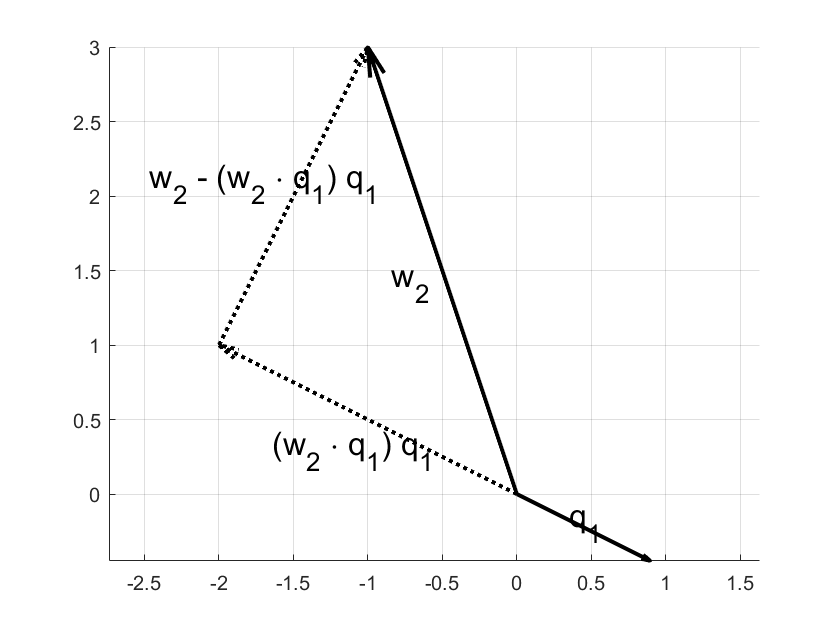

figure, hold on
plot_vector([0 0], q1, 'k', 'q_1')
plot_vector([0 0], w2, 'k', 'w_2')
plot_vector([0 0], proj_w2_on_q1, 'k:', '(w_2 \cdot q_1) q_1')
plot_vector(proj_w2_on_q1, w2-proj_w2_on_q1, 'k:', 'w_2 - (w_2 \cdot q_1) q_1')

So all that remains to complete our new orthonormal basis is to divide it by its length.  We'll call the result $q_2$.

q2 = v2 / norm(v2)

q2 =     0.4472
    0.8944


Wonderful, we now have a brand new *orthonormal* basis $\{q_1 \ q_2\}$.  Let's put the vectors into a matrix $Q$ for safekeeping.

Q = [q1 q2]

Q =     0.8944    0.4472
   -0.4472    0.8944


#### Exercise

In a (separate) MATLAB editor tab, go through this same process of orthonormalising the basis yourself.  Don't refer to back to the example code unless you really get stuck.▫

### 3.2.2 Coordinate vectors for an orthonormal basis

Armed with our new orthonormal basis, let's now find the coordinate vector of $b$ relative to this basis.

[Video](https://web.microsoftstream.com/video/880b7e9d-998e-48ca-8aca-9dbb46aabbc8)

#### Exercise

On a piece of paper, go through this same process of finding the coordinate vector relative to the orthonormal basis yourself by hand.  Don't refer to back to the video unless you really get stuck.▫

In MATLAB, we can easily confirm that $\{q_1, q_2\}$ is indeed an orthonormal basis.  We just need to take the dot products $q_1 \cdot q_1$, $q_2 \cdot q_2$, and $q_1 \cdot q_2$.  The first two should be 1 (the vectors are normalised), and the third should be zero (the vectors are orthogonal).  Remember we stored the basis vectors in the matrix $Q = [q_1 \ q_2]$.  So $Q^T Q=\left\lbrack \begin{array}{c}
{q_1 }^T \\
{q_2 }^T 
\end{array}\right\rbrack$$[q_1 \ q_2]$$=\left\lbrack \begin{array}{cc}
{q_1 }^T q_1  & {{q_1 }^T q}_2 \\
{q_2 }^T q_1  & {q_2 }^T q_2 
\end{array}\right\rbrack$ and we get all the dot product combinations in one go.

Q'*Q

ans =     1.0000   -0.0000
   -0.0000    1.0000


The diagonal entries are all one, corresponding to basis vectors dotted with themselves.  The off-diagonal entries are zero, corresponding to basis vectors dotted with other basis vectors.  So all is well, we do indeed have an orthonormal basis.

Wait, what did we just say?  This matrix $Q$ has the property that $Q^T Q = I$.  This is indeed no ordinary matrix!

As we saw in the video, to find the coordinate vector of $b$ relative to this new orthonormal basis, we could still think of solving the linear system $Qc = b$.  But now, it requires no significant work on our part, because we can just multiply both sides by $Q^T$, and hey presto, $Q^TQc = Q^Tb$ and so $c = Q^T b$.

c_onb = Q' * b

c_onb =     1.7889
    3.1305


Now, this is really something special.  We've managed to solve the required linear system of equations without needing to perform *any* row operations at all.  The orthonormal basis gave us the property that $Q^T Q = I$, which made the step of finding the coordinate vector completely trivial.

Here's the picture showing our good old red vector in terms of the *standard basis* $\{e_1,e_2\}$ and in terms of our new orthonormal basis $\{q_1,q_2\}$.

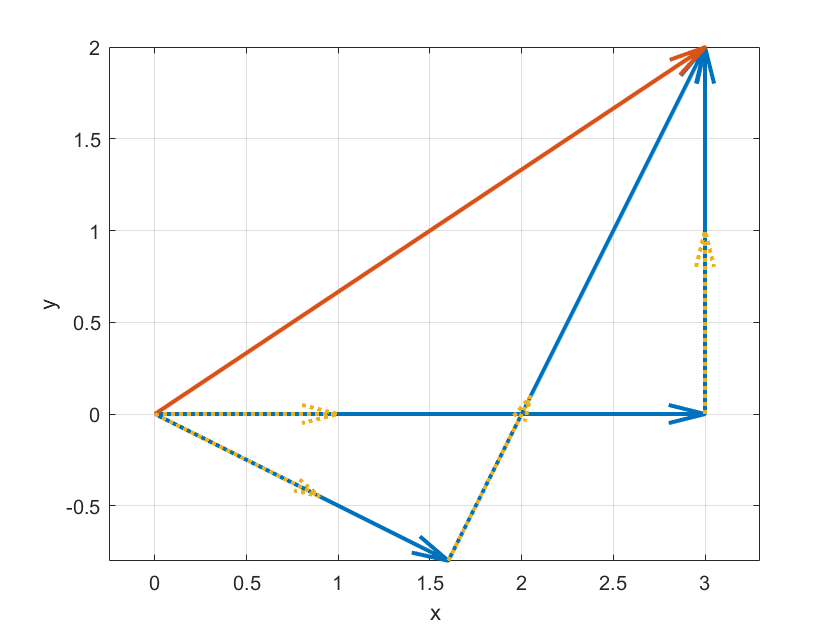

figure
plot_lincomb(b, eye(2))
hold on
plot_lincomb(c_onb, Q)

Our new orthonormal basis is really just a rotation of the standard basis (by what angle?).

## 3.3 The Gram-Schmidt process

OK, we've got the case of a two-dimensional basis down pat.  But how do we generalise?

[Video](https://web.microsoftstream.com/video/260241ea-cbd6-4b45-b02b-6d4623677205)

(Anton 6.3)  Note that in this section of Anton's book, he uses the notation $\langle u,v \rangle$ which just means $u \cdot v$.  (In Chapter 6 we'll give some more consideration to this notation.)

As we saw in the video, for the $i$th step of the orthonormalisation process, starting with $w_i$, we subtract off its projection onto the space spanned by *all* the previous orthonormal basis vectors $q_j$ for $j = 1 \ldots i-1$ to obtain $v_i$, and then we divide $v_i$ by its norm to obtain $q_i$.

That's a mouthful, so here it is step-by-step.  At each step, we form a $v$, and then we normalise the $v$ to get a $q$.


$$v_1 = w_1 ; \qquad \qquad \qquad \qquad\qquad \qquad \qquad \qquad  \quad \ \ q_1 = v_1 / \|v_1\|$$



$$v_2 = w_2 - (w_2 \cdot q_1) \,q_1; \qquad\qquad \qquad \qquad \qquad  \qquad\ q_2 = v_2 / \|v_2\|$$



$$v_3 = w_3 - (w_3 \cdot q_1) \,q_1 - (w_3 \cdot q_2) \,q_2; \qquad \qquad \qquad \quad q_3 = v_3 / \|v_3\|$$



$$v_4 = w_4 - (w_4 \cdot q_1) \,q_1 - (w_4 \cdot q_2) \,q_2 - (w_4 \cdot q_3) \,q_3; \quad\  q_4 = v_4 / \|v_4\|$$


and in general,


$$v_i = w_i - \sum_{j = 1}^{i-1} (w_i \cdot q_j) \,q_j; \qquad \qquad 
 \qquad \qquad \qquad \quad \ 
q_i = v_i / \|v_i\|$$
   

This procedure is known as the ***Gram-Schmidt process****.  *It takes as input an arbitrary set of linearly independent vectors $\{w_1, \ldots w_k\}$ and computes two sets of mutually orthogonal vectors that span the same space:  $\{v_1, \ldots v_k\}$ and $\{q_1, \ldots q_k\}$.  In other words, it returns an *orthogonal basis* $\{v_1, \ldots v_k\}$ and an *orthonormal basis* $\{q_1, \ldots q_k\}$ for the space spanned by the vectors $\{w_1, \ldots w_k\}$.  Usually it's the orthonormal basis (the $q$s) that we care about, with the intermediate orthogonal basis (the $v$s) just a byproduct of the calculations required.

### 3.3.1 A larger example

OK, now that we've got our eye in, let's take a larger example.  We will consider the matrix $A$ that we analysed in Chapter 1 and 2.

clear
m = 8;
n = 5;
A = [1    -1     0     1     0
     1     0     1    -3    -4
     2     2     4     0    -2
     1     0     1     2     1
     3     3     6     0    -3
     0     2     2     2     2
     0     1     1     4     4
     3    -2     1     2    -1]

A =      1    -1     0     1     0
     1     0     1    -3    -4
     2     2     4     0    -2
     1     0     1     2     1
     3     3     6     0    -3
     0     2     2     2     2
     0     1     1     4     4
     3    -2     1     2    -1


Our task will be to calculate an orthonormal basis for its column space.

Performing this process by hand quickly gets tedious, so we'll work entirely in MATLAB for this example.

Before we get too far ahead of ourselves though, we recall from seeing this matrix in previous chapters that its columns aren't all linearly independent.  Since the Gram-Schmidt process must start from a basis, we need to strip out the redundant columns of $A$.  We'll simply choose as our basis the columns of $A$ corresponding to the basic variables, as we learned about in Chapter 1, Section 1.4.3.

[R, ~, bv] = rref2(A)

R =      1     0     1     0    -1
     0     1     1     0     0
     0     0     0     1     1
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


bv =      1     2     4


The outputs here are the reduced row echelon form $R$ and the indices of the basic variables $bv$.  We really just need the latter, which identifies the basic columns of $A$ as columns 1, 2 and 4 (which we can confirm is correct by looking at the locations of the pivots in the RREF).

So the basic columns are columns 1,2 and 4 of $A$.  Since all we need from $A$ for this question is its column space, let's just overwrite the variable `A` with the basic columns alone.

A = A(:, bv)

A =      1    -1     1
     1     0    -3
     2     2     0
     1     0     2
     3     3     0
     0     2     2
     0     1     4
     3    -2     2


Now for the Gram-Schmidt process.  Let's be good students, and show all our working.  We'll find out later in fact, that keeping all the intermediate calculations in variables will pay off.

We'll keep track of *three* sets of vectors.  The first set, $\{w_1, w_2, w_3\}$ are our original basis vectors.  In terms of the matrix A, these are A`(:,1), A(:,2), A(:,3)` (using MATLAB notation).

The second set, $\{v_1, v_2, v_3\}$ will be an *orthogonal* set of vectors, spanning the same space as $\{w_1, w_2, w_3\}$ but satisfying $v_i \cdot v_j = 0, i \neq j$.

The third set, $\{q_1, q_2, q_3\}$ will be an *orthonormal *set of vectors, spanning the same space as both $\{w_1, w_2, w_3\}$ and $\{v_1, v_2, v_3\}$, but satisfying $q_i \cdot q_j = 0, i \neq j$ *and* $q_i \cdot q_i = 1$.  For short, we often write $q_i \cdot q_j = \delta_{ij}$ where $\delta_{ij}$ is called the Kronecker delta, defined by $\delta_{\textrm{ij}} =\left\lbrace \begin{array}{cc}
1, & i=j\\
0, & i\not= j
\end{array}\right.$.

In terms of the $v_i$, the $q_i$ are just $q_i = v_i / \|v_i\|$.

With all that in mind, let's go!  We start by simply setting $v_1 = w_1$.

v1 = A(:,1)

v1 =      1
     1
     2
     1
     3
     0
     0
     3


Then we divide $v_1$ by its norm to get $q_1 = v_1 / \|v_1\|$.

norm_v1 = norm(v1)

norm_v1 = 5

q1 = v1 / norm_v1

q1 =     0.2000
    0.2000
    0.4000
    0.2000
    0.6000
         0
         0
    0.6000


Now, our goal is to find $v_2$ by subtracting from $w_2$ the projection of $w_2$ onto $q_1$.

w2 = A(:,2);
w2_dot_q1 = dot(w2, q1)

w2_dot_q1 = 1.2000

v2 = w2 - w2_dot_q1 * q1

v2 =    -1.2400
   -0.2400
    1.5200
   -0.2400
    2.2800
    2.0000
    1.0000
   -2.7200


Now we can calculate $q_2$ by dividing $v_2$ by its norm.

norm_v2 = norm(v2)

norm_v2 = 4.6433

q2 = v2 / norm_v2

q2 =    -0.2671
   -0.0517
    0.3274
   -0.0517
    0.4910
    0.4307
    0.2154
   -0.5858


One more basis vector to go!  We form $v_3$ by subtracting from $w_3$ the projection of $w_3$ onto *both* $q_1$ *and* $q_2$.

w3 = A(:,3);
w3_dot_q1 = dot(w3, q1)

w3_dot_q1 = 1.2000

w3_dot_q2 = dot(w3, q2)

w3_dot_q2 = 0.3360

v3 = w3 - w3_dot_q1 * q1 - w3_dot_q2 * q2

v3 =     0.8497
   -3.2226
   -0.5900
    1.7774
   -0.8850
    1.8553
    3.9276
    1.4768


And now we get $q_3$ in the usual way, by dividing $v_3$ by its norm.

norm_v3 = norm(v3)

norm_v3 = 6.0371

q3 = v3 / norm_v3

q3 =     0.1407
   -0.5338
   -0.0977
    0.2944
   -0.1466
    0.3073
    0.6506
    0.2446


We now have two new bases to go with our matrix $A = [w_1\ w_2\ w_3]$.  The matrix $V = [v_1\ v_2\ v_3]$ is the matrix of *orthogonal* basis vectors.  The matrix $Q = [q_1\ q_2\ q_3]$ is the matrix of *orthonormal* basis vectors.

V = [v1 v2 v3]  % orthogonal basis for span{w_1, w_2, w_3}

V =     1.0000   -1.2400    0.8497
    1.0000   -0.2400   -3.2226
    2.0000    1.5200   -0.5900
    1.0000   -0.2400    1.7774
    3.0000    2.2800   -0.8850
         0    2.0000    1.8553
         0    1.0000    3.9276
    3.0000   -2.7200    1.4768


Q = [q1 q2 q3]  % orthonormal basis for span{w_1, w_2, w_3}

Q =     0.2000   -0.2671    0.1407
    0.2000   -0.0517   -0.5338
    0.4000    0.3274   -0.0977
    0.2000   -0.0517    0.2944
    0.6000    0.4910   -0.1466
         0    0.4307    0.3073
         0    0.2154    0.6506
    0.6000   -0.5858    0.2446


#### Exercise

In a (separate) MATLAB editor tab, go through the Gram-Schmidt process for this matrix yourself.  Don't refer to back to the example code unless you really get stuck.▫

Let's recap.  We started with a three-dimensional subspace of $\mathbb{R}^8$, which we had a basis for:

A

A =      1    -1     1
     1     0    -3
     2     2     0
     1     0     2
     3     3     0
     0     2     2
     0     1     4
     3    -2     2


We then applied a method which we now know is called the *Gram-Schmidt process* to find an orthonormal basis for this same space.

Q

Q =     0.2000   -0.2671    0.1407
    0.2000   -0.0517   -0.5338
    0.4000    0.3274   -0.0977
    0.2000   -0.0517    0.2944
    0.6000    0.4910   -0.1466
         0    0.4307    0.3073
         0    0.2154    0.6506
    0.6000   -0.5858    0.2446


Let's just emphasise that last point again.  These two sets of vectors *span the same space, *which is a three-dimensional subspace of $\mathbb{R}^8$.  So the orthonormal basis $Q$ might as well be considered the "standard basis" for this space.  There's no sense in which we could be using say $e_1$, $e_2$, etc. or anything like that as a basis for this space.  This is a very particular subspace of $\mathbb{R}^8$ which is determined by that matrix $A$ we started with.  Only now we have a much more convenient basis for that space than the actual columns of $A$.

### 3.3.2 Finding coordinate vectors: a comparison

Returning to the general case where we have $k$ vectors in our basis, let's see how using the orthonormal basis (i.e., $Q$) makes many computations easier.  Note that neither $A$ nor $Q$ are square matrices in general.  This is again a reminder that we're dealing with only a $k$-dimensional *subspace* of $\mathbb{R}^n$.

(In this video I use $W$ instead of $A$ -- apologies for the inconsistent notation.)

[Video](https://web.microsoftstream.com/video/cbc226cb-745d-495b-a1bd-2fed46277bc6)

Now in MATLAB again, let's take the concrete example of $A$ and $Q$ we've been working with.  Suppose we are tasked with finding the coordinate vector of 

b = [0 5 6 0 9 0 -3 2]'

b =      0
     5
     6
     0
     9
     0
    -3
     2


relative to these two bases.  For the non-orthonormal basis in $A$ this requires solving a full linear system of equations.  We'll compute the full RREF to emphasise this point.

RREF = rref2([A b]), c1 = RREF(1:3, end)

RREF =      1     0     0     2
     0     1     0     1
     0     0     1    -1
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


c1 =      2
     1
    -1


For the orthonormal basis in $Q$, we need only find the dot products of $b$ against the basis vectors.

c2 = Q' * b

c2 =    10.0000
    4.3073
   -6.0371


Either representation gives the same vector:

A*c1, Q*c2

ans =      0
     5
     6
     0
     9
     0
    -3
     2


ans =    -0.0000
    5.0000
    6.0000
   -0.0000
    9.0000
         0
   -3.0000
    2.0000


Although notice that because we're using floating point arithmetic, we shouldn't expect *exact* equality.

isequal(A*c1, Q*c2)

ans = logical
   0

A better test for floating point vectors is to check that the norm of the difference is small.

norm(A*c1 - Q*c2)

ans = 9.2222e-16

The vectors $Ac_1$ and $Qc_2$ are equal to within roundoff error.

#### Exercise

In a (separate) MATLAB editor tab, go through the process of finding the coordinate vectors for $b$ yourself.  Don't refer to back to the example code unless you really get stuck.▫

### 3.3.3 Coordinate vectors of orthogonal projections

Now it's time for a little magic trick.  Observe, the following vector $u$ which is *not* in the column space of $A$.

u = rand(8,1)

u =     0.4456
    0.6463
    0.7094
    0.7547
    0.2760
    0.6797
    0.6551
    0.1626


If we try to find its "representation" in terms of the basis in $A$, we find there is no solution to the equation $Ac = u$.

rref2([A u])

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


We see that $\textrm{rank}(A) = 3$ but $\textrm{rank}([A|u]) = 4$, so the system is inconsistent.  No such coefficient vector $c$ exists.

But here's the magic trick.  For the orthonormal basis in $Q$, there's nothing to stop us just calculating $c = Q^T u$ just like we did before for $b$.

c = Q' * u

c =     0.9162
    0.5149
    0.5050


Despite the inconsistency of the equation $Qc = u$, evidently we can *still* calculate a "coordinate vector" using the orthonormal basis.  But, it's the coordinate vector of...*what*...exactly?  Certainly not $u$, because we already established that $u$ isn't in the space spanned by this basis.

uP = Q*c  % you will see, uP and u are definitely not the same vectors

uP =     0.1168
   -0.1129
    0.4857
    0.3053
    0.7286
    0.3770
    0.4394
    0.3716


u

u =     0.4456
    0.6463
    0.7094
    0.7547
    0.2760
    0.6797
    0.6551
    0.1626


In fact the vector $u_P = Qc$ is actually the *orthogonal projection* of $u$ onto $\textrm{span}\{q_1, q_2, q_3\}$.  Let's confirm this is true.  We know from Chapter 2 that the orthogonal projector onto the space is given by $P = Q (Q^T Q)^{-1} Q^T$.  But remember that $Q^T Q$ has an especially simple form:

Q'*Q

ans =     1.0000    0.0000         0
    0.0000    1.0000   -0.0000
         0   -0.0000    1.0000


$Q^T Q$ is the identity matrix.  So the orthogonal projector takes the simple form $P = QQ^T$, which is true only because the columns of $Q$ form an *orthonormal* basis.

P = Q*Q'

P =     0.1311   -0.0213   -0.0212    0.0952   -0.0318   -0.0718    0.0341    0.3109
   -0.0213    0.3276    0.1152   -0.1145    0.1729   -0.1863   -0.3584    0.0197
   -0.0212    0.1152    0.2767    0.0343    0.4151    0.1110    0.0069    0.0243
    0.0952   -0.1145    0.0343    0.1293    0.0515    0.0682    0.1804    0.2223
   -0.0318    0.1729    0.4151    0.0515    0.6226    0.1665    0.0104    0.0365
   -0.0718   -0.1863    0.1110    0.0682    0.1665    0.2800    0.2927   -0.1771
    0.0341   -0.3584    0.0069    0.1804    0.0104    0.2927    0.4696    0.0330
    0.3109    0.0197    0.0243    0.2223    0.0365   -0.1771    0.0330    0.7630


That being the case, we can see that $u_P = Qc = Q Q^T u = P u$.

Again, since we're using floating point arithmetic, we shouldn't expect *exact* equality when testing two vectors for equality.

P*u, uP  % these look the same on the screen, but are they?

ans =     0.1168
   -0.1129
    0.4857
    0.3053
    0.7286
    0.3770
    0.4394
    0.3716


uP =     0.1168
   -0.1129
    0.4857
    0.3053
    0.7286
    0.3770
    0.4394
    0.3716


norm(P*u - uP)

ans = 2.0254e-16

The vectors $Pu$ and $u_P$ are equal to within roundoff error.  Thus, $u_P = Qc$ is indeed just the orthogonal projection of $u$ onto the space.

#### Exercise

In a (separate) MATLAB editor tab, go through the process of "finding" the coordinate vector for $u$ yourself, and verifying that it really is the coordinate vector of $u$'s orthogonal projection.  Don't refer to back to the example code unless you really get stuck.▫

## 3.4 Orthonormal bases summarised

There is so much to like about orthonormal bases!  In summary, if you have an orthonormal basis $\{q_1, q_2, \ldots q_k\}$ and arbitrary vector $u$, then:

if $u \in \textrm{span}\{q_1, q_2, \ldots q_k\}$:  $Q^T u$ is the coordinate vector of $u$, and hence $QQ^T u$ is just $u$ itself.

if $u \notin \textrm{span}\{q_1, q_2, \ldots q_k\}$:  $Q^T u$ is the coordinate vector of $u$'s orthogonal projection onto $\textrm{span}\{q_1, q_2, \ldots q_k\}$, and hence $QQ^T u$ is the orthogonal projection.

If you have a basis $\{w_1, w_2, \ldots w_k\}$, but it's *not *orthonormal, you can make it orthonormal by applying the Gram-Schmidt process.

## 3.5 The QR decomposition

(Anton 6.3)

The Gram-Schmidt process is clearly an indispensable tool in linear algebra.  Surely MATLAB has this algorithm built-in.  Indeed it does, but to see how it works, we need to think about how to best summarise all the work that goes on the Gram-Schmidt process.

[Video](https://web.microsoftstream.com/video/e4263ae5-cdfe-4a67-9902-aee29a501afb)

Here is that process in the video described in general.  Start from the Gram-Schmidt process.

$v_i = w_i - \sum_{j = 1}^{i-1} (w_i \cdot q_j) \,q_j$      (i)

$q_i = v_i / \|v_i\|$                           (ii)

First, we can use (ii) to see that $v_i$ is $\|v_i\| q_i$.  Then we make that substitution in (i) to get:


$$\|v_i\| q_i = w_i - \sum_{j = 1}^{i-1} (w_i \cdot q_j)\, q_j$$


Isolate $w_i$:


$$w_i = \sum_{j = 1}^{i-1} (w_i \cdot q_j)\, q_j + \|v_i\| q_i $$


Now we cleverly write the whole sum as a matrix-vector product over all the $q_j$s, with coefficients of zero where they don't appear in the sum:


$$w_i = \bigg[q_1 \ q_2 \ \cdots \ q_{i-1} \ q_i \ q_{i+1} \ \cdots \ q_k \bigg]$$

$$\left\lbrack \begin{array}{c}
w_i \cdot q_1 \\
w_i \cdot q_2 \\
\vdots \;\\
w_i \cdot q_{i-1} \\
\left\|v_i \right\|\\
0\\
\vdots \\
0
\end{array}\right\rbrack$$


Or very compactly,


$$A = QR$$


where $A$ and $Q$ are the matrices of the $w_i$ and $q_i$ vectors (as usual), and the $i$th column of $R$ has the form shown above.  Notice therefore, that $R$ is *upper triangular*.  So in fact, the Gram-Schmidt process generates for us a brand new matrix decomposition, known (unimaginatively) as the ***QR decomposition***.

Let's build this decomposition for our example and confirm it checks out.  We already have the matrix $Q$, whose columns you recall are orthonormal:

Q

Q =     0.2000   -0.2671    0.1407
    0.2000   -0.0517   -0.5338
    0.4000    0.3274   -0.0977
    0.2000   -0.0517    0.2944
    0.6000    0.4910   -0.1466
         0    0.4307    0.3073
         0    0.2154    0.6506
    0.6000   -0.5858    0.2446


Now we just need to form the upper triangular matrix $R$ by assembling all the norms and dot products that we calculated as part of our working into the matrix as shown.

R = [norm_v1  w2_dot_q1  w3_dot_q1
         0      norm_v2  w3_dot_q2
         0         0      norm_v3]

R =     5.0000    1.2000    1.2000
         0    4.6433    0.3360
         0         0    6.0371


According to the analysis above, we should have that $A = QR$.  Let's confirm.

A, Q*R

A =      1    -1     1
     1     0    -3
     2     2     0
     1     0     2
     3     3     0
     0     2     2
     0     1     4
     3    -2     2


ans =     1.0000   -1.0000    1.0000
    1.0000         0   -3.0000
    2.0000    2.0000   -0.0000
    1.0000         0    2.0000
    3.0000    3.0000    0.0000
         0    2.0000    2.0000
         0    1.0000    4.0000
    3.0000   -2.0000    2.0000


As usual, because we worked with floating point arithmetic, rather than exact arithmetic, we don't expect *precise* equality.  But the two results look identical to the digits shown.  We'll check the norm of the difference to be sure:

norm(A - Q*R) % yes, you can take norms of matrices, not just vectors!

ans = 4.4516e-16

The difference is of the order of roundoff error, so we've certainly got it right.

The QR decomposition is the way that MATLAB provides the equivalent of the Gram-Schmidt process.  Here's how to access it:

[Q1, R1] = qr(A, 0)  % note the second "zero" argument

Q1 =    -0.2000   -0.2671    0.1407
   -0.2000   -0.0517   -0.5338
   -0.4000    0.3274   -0.0977
   -0.2000   -0.0517    0.2944
   -0.6000    0.4910   -0.1466
         0    0.4307    0.3073
         0    0.2154    0.6506
   -0.6000   -0.5858    0.2446


R1 =    -5.0000   -1.2000   -1.2000
         0    4.6433    0.3360
         0         0    6.0371


Comparing MATLAB's output $Q_1$ to our own matrix $Q$, we can see that there are actually some differences in the signs of the entries:

Q, Q1

Q =     0.2000   -0.2671    0.1407
    0.2000   -0.0517   -0.5338
    0.4000    0.3274   -0.0977
    0.2000   -0.0517    0.2944
    0.6000    0.4910   -0.1466
         0    0.4307    0.3073
         0    0.2154    0.6506
    0.6000   -0.5858    0.2446


Q1 =    -0.2000   -0.2671    0.1407
   -0.2000   -0.0517   -0.5338
   -0.4000    0.3274   -0.0977
   -0.2000   -0.0517    0.2944
   -0.6000    0.4910   -0.1466
         0    0.4307    0.3073
         0    0.2154    0.6506
   -0.6000   -0.5858    0.2446


These differences are purely cosmetic, and amount to MATLAB sometimes picking $-q_i$ to use in the basis, rather than $q_i$.  Clearly either are acceptable as a basis vector.  The corresponding sign changes are to be found in the $R$ as well.

R, R1

R = 3×3
    5.0000    1.2000    1.2000
         0    4.6433    0.3360
         0         0    6.0371


R1 = 3×3
   -5.0000   -1.2000   -1.2000
         0    4.6433    0.3360
         0         0    6.0371


### 3.5.1 Solving the least squares problem using QR decomposition

[Video](https://web.microsoftstream.com/video/c8cc32da-c613-47e5-bdda-770bf8730f5c)

Representing the Gram-Schmidt process in the form of a QR decomposition $A = QR$ is more than just a convenient bit of bookkeeping.  Having a matrix relationship between the original basis (the columns of $A$) and the orthonormal basis (the columns of $Q$) allows us to substitute $QR$ for $A$ in any equation in which $A$ appears .  This can often greatly simplify a problem if it involves products of transposes, because an expression of the form $Q^T Q$ it can be replaced with $I$.

A good example is using the QR decomposition to simplify the normal equations.  Suppose we have a rectangular matrix $A$ with full column rank, and we find the QR decomposition of this matrix.  Then the normal equations $A^TA x = A^T b$ beome:


$$A^TA x = A^T b$$



$$(QR)^T (QR) x = (QR)^T b$$


$R^T Q^T Q R x = R^T Q^T b$   (notice the appearance of $Q^T Q$, which is simply $I$)


$$R^T R x = R^T Q^T b$$


$Rx = Q^T b$  (assuming $R^T$ is invertible, which it will be, since $A$ has full column rank)

Thus, to solve the least squares problem $x = \textrm{argmin}_{x^* \in \mathbb{R}^n} \|b - Ax^*\|$ we can find the QR decomposition $A = QR$ and then solve the *triangular* linear system $Rx = Q^T b$ using backward substitution.  There's no need to actually form the normal equations, and no need to apply any row operations.  The bulk of the work is instead finding the QR decomposition of $A$.

Let's try out the two different ways we've learned to solve the least squares problem: normal equations and QR decomposition.

[Video](https://web.microsoftstream.com/video/d916c8af-d127-4b53-8779-8bbb729acd9d)

#### Exercise

On a piece of paper, solve this same problem yourself by hand doing all the steps of working.  Don't refer to back to the example video unless you really get stuck.▫

Now in MATLAB we'll go one better, and fit a quadratic $y = c_0 + c_1 t + c_2 t^2$ to some (different) data.

t = (0:0.1:1)'  % t values from 0 to 1

t = 11×1
         0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


b = 1 + 0.5*t + 2*t.^2 + 0.1*randn(size(t)) % RHS is a quadratic plus random noise

b = 11×1
    0.8886
    1.0693
    1.3333
    1.2530
    1.5571
    1.7274
    2.1317
    2.2211
    2.6833
    3.1253


A = t.^(0:2)  % the coefficient matrix, with more rows than columns

A = 11×3
    1.0000         0         0
    1.0000    0.1000    0.0100
    1.0000    0.2000    0.0400
    1.0000    0.3000    0.0900
    1.0000    0.4000    0.1600
    1.0000    0.5000    0.2500
    1.0000    0.6000    0.3600
    1.0000    0.7000    0.4900
    1.0000    0.8000    0.6400
    1.0000    0.9000    0.8100


First way: solve the normal equations $A^TAc = A^Tb$.

ATA = A'*A, ATb = A'*b

ATA = 3×3
   11.0000    5.5000    3.8500
    5.5000    3.8500    3.0250
    3.8500    3.0250    2.5333


ATb = 3×1
   21.6002
   13.6393
   10.5724


c1 = ATA \ ATb

c1 = 3×1
    0.9758
    0.5633
    2.0178


Second way: use the QR decomposition.  $A = QR$ and solve $Rc = Q^Tb$.

[Q,R] = qr(A, 0)

Q = 11×3
   -0.3015   -0.4767    0.5121
   -0.3015   -0.3814    0.2048
   -0.3015   -0.2860   -0.0341
   -0.3015   -0.1907   -0.2048
   -0.3015   -0.0953   -0.3073
   -0.3015   -0.0000   -0.3414
   -0.3015    0.0953   -0.3073
   -0.3015    0.1907   -0.2048
   -0.3015    0.2860   -0.0341
   -0.3015    0.3814    0.2048


R = 3×3
   -3.3166   -1.6583   -1.1608
         0    1.0488    1.0488
         0         0    0.2929


c2 = R \ (Q'*b)

c2 = 3×1
    0.9758
    0.5633
    2.0178


Bonus third way: since we're using floating point arithmetic, in MATLAB you can actually just use backslash on the rectangular matrix $A$!

c3 = A \ b

c3 = 3×1
    0.9758
    0.5633
    2.0178


The backslash operator applied to a rectangular matrix defaults to solving the least squares problem.  But there's no magic here -- behind the scenes, MATLAB is just using the QR decomposition.

#### Exercise

In a (separate) MATLAB editor tab, solve this same problem yourself in the three different ways shown.  Don't refer to back to the example code unless you really get stuck.▫

## **3.6 Summary**

- Orthogonal bases $\{v_1, v_2, \ldots v_k\}$ satisfy $v_i \cdot v_j = 0, i \neq j$.

- Orthonormal bases $\{q_1, q_2, \ldots q_k\}$ satisfy $q_i \cdot q_j = \delta_{ij}$, where $\delta_{ij}$ is the Kronecker delta.

-     Equivalently, if $Q = [q_1\ q_2\ \cdots\ q_k]$, then $Q^TQ = I$.

- The Gram-Schmidt process constructs an orthogonal basis $\{v_1, v_2, \ldots v_k\}$ and an orthonormal basis  $\{q_1, q_2, \ldots q_k\}$ from an arbitrary basis $\{w_1, w_2, \ldots w_k\}$.

-     The relationship between the original matrix of basis vectors $A$ and the new matrix $Q$ of orthonormal basis vectors is $A = QR$, where $R$ is a square upper triangular matrix.

- Orthonormal bases make finding coordinate vectors and orthogonal projections very convenient.

-     if $u \in \textrm{span}\{q_1, q_2, \ldots q_k\}$:  $Q^T u$ is the coordinate vector of $u$, and hence $QQ^T u$ is just $u$ itself.

-     if $u \notin \textrm{span}\{q_1, q_2, \ldots q_k\}$:  $Q^T u$ is the coordinate vector of $u$'s orthogonal projection onto $\textrm{span}\{q_1, q_2, \ldots q_k\}$, and hence $QQ^T u$ is the orthogonal projection.

- The QR factorisation $A = QR$ converts the normal equations $A^T Ax = A^T b$ to the triangular linear system $Rx = Q^T b$.

-     You can form the QR factorisation $A = QR$ in MATLAB using `[Q,R] = qr(A, 0)`.

-     In MATLAB, applying "backslash" to a rectangular floating point linear system solves the least squares problem.